% data loaded from Kfdata file 
% t: a vector of times associated with the input signals.
% u: a matrix whose columns are the robot inputs at the times associated with t. This signal
% is the signal applied to the robot, it does not include the noise terms in v[k].
% t y: a vector of times associated with the GPS measurement.
% y: a matrix whose columns are the noisy GPS measurements taken at the times in t y.
% q groundtruth: a matrix whose columns are the robot states at the times associated the
% times in t.

%prediction step
load kfData.mat t u t_y y q_groundtruth 
n = size(t,2);
V = [0.2590 0.0010; 0.0010 0.0625];
W = [1.8817 0.0632; 0.0632 2.1384];
T = 0.01

T = 0.0100

q_hat(:,1) = [0.355;-1.59;0.682]

q_hat =     0.3550    0.3989    0.4415    0.4840    0.5248    0.5728    0.6165    0.6608    0.6967    0.7393    1.4234    1.4648    1.5067    1.5394    1.5753    1.6202    1.6598    1.7049    1.7478    1.7852    2.4025    2.4448    2.4750    2.5186    2.5596    2.5963    2.6376    2.6783    2.7226    2.7619    2.9163    2.9616    3.0086    3.0528    3.0978    3.1362    3.1701    3.2121    3.2535    3.2897    3.0280    3.0728    3.1116    3.1533    3.1967    3.2400    3.2805    3.3157    3.3578    3.4014
   -1.5900   -1.5543   -1.5200   -1.4855   -1.4529   -1.4144   -1.3792   -1.3432   -1.3144   -1.2798    1.6218    1.6560    1.6903    1.7169    1.7459    1.7821    1.8140    1.8501    1.8845    1.9149    2.1653    2.1992    2.2234    2.2579    2.2904    2.3193    2.3516    2.3835    2.4180    2.4489    2.4359    2.4705    2.5060    2.5397    2.5740    2.6032    2.6291    2.6611    2.6927    2.7205    2.7744    2.8113    2.8431    2.8773    2.9126    2.9479    2.9810    3.0099    3.0442 

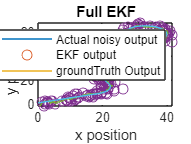

P = [25 0 0;0 25 0;0 0 0.154];
H = [1 0 0;0 1 0];
i = 1;


for k=1:1:n-1
    
    F = [1 0 -T*(u(1,k))*sin(q_hat(3,k));
        0 1 T*(u(1,k))*cos(q_hat(3,k));
        0 0 1];
    G = [T*cos(q_hat(3,k)) 0;
        T*sin(q_hat(3,k)) 0;
        0 T];
    gamma = [T*cos(q_hat(3,k)) 0;
        T*sin(q_hat(3,k)) 0;
        0 T];
    u_k = [u(1,k);u(2,k)];
    
    %predict
    v = mvnrnd([0;0],V);
    w = mvnrnd([0;0],W);
    q_hat(:,k+1) = [(q_hat(1,k) + T*(u(1,k) +v(1))*cos(q_hat(3,k)));
                    (q_hat(2,k) + T*(u(1,k) +v(1))*sin(q_hat(3,k)));
                    q_hat(3,k) + T*(u(2,k)+v(2))];

    P = F*P*transpose(F) + gamma*V*transpose(gamma);

    %q_hat(:,k+1) = F*q_hat(:,k) + G*u_k;
    r = rem(k,10);

    if r == 0
     %update 
    v_dash = y(:,i) - H*q_hat(:,k+1);
    S = H*P*transpose(H) + W/100;
    R = P*transpose(H)*inv(S);

    q_hat(:,k+1) = q_hat(:,k+1) + R*v_dash;
    P = P - R*H*P;
    i = i+1;
    end 
end

hold on
scatter(y(1,:),y(2,:))
plot(q_hat(1,:),q_hat(2,:))
plot(q_groundtruth(1,:),q_groundtruth(2,:))
legend('Actual noisy output','EKF output', 'groundTruth Output')
title('Full EKF')
xlabel('x position') 
ylabel('y position')
hold off